# Progress Bar

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 300 60]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

progressWidget = wt.ProgressBar(gridObj);
progressWidget.ShowCancel = true;

Assign a callback:

progressWidget.CancelPressedFcn = @(h,e)disp("Cancel Pressed!")

progressWidget =   ProgressBar with properties:

     CancelPressedFcn: @(h,e)disp("Cancel Pressed!")

    ShowTimeRemaining: on
           ShowCancel: on
        Indeterminate: off
             BarColor: [0.5000 0.7000 1]
                Value: 0
           StatusText: ""
              Running: off
      CancelRequested: off
            StartTime: NaT
          ElapsedTime: NaN
        RemainingTime: NaN

             Position: [100 100 100 100]
                Units: 'pixels'

  Show all properties


Start the progress bar

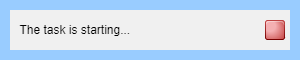

progressWidget.startProgress("The task is starting...");

Update the progress bar with a value between 0 and 1 as the task progresses:

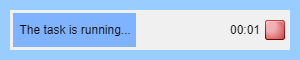

progressWidget.setProgress(0.5, "The task is running...");

Then, when the task is done, mark it finished:

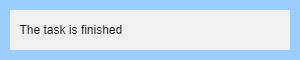

progressWidget.finishProgress("The task is finished");

If you instead want an indeteriminate progress bar:

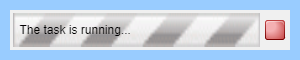

progressWidget.Indeterminate = true;
progressWidget.startProgress("The task is running...");

*Copyright 2020-2025 The MathWorks, Inc.*